# Mi primer live script de matrices

#### Primer ejemplo

A = [1 0; -1 2];
B = [1 0; -2 2];
C = A*B;
disp("El resultado de la multiplicación es");

El resultado de la multiplicación es


disp(C)

       1              0       
      -5              4       



fprintf("Imprime el valor de la primer entrada de A , %f",A(1,1))

Imprime el valor de la primer entrada de A , 1.000000

#### Segundo ejemplo

Definimos a la base canónica

e1 = [1 ; 0 ; 0]

e1 =        1       
       0       
       0       


e2 = [0 ; 1 ; 0]

e2 =        0       
       1       
       0       


e3 = [0 ; 0 ; 1]

e3 =        0       
       0       
       1       


v = [1 2 1]

v =        1              2              1       


fprintf("La segunda coordenada del vector es, %d", v(2))

La segunda coordenada del vector es, 2

fprintf("La tercer coordenada del vector es: %d", v(3))

La tercer coordenada del vector es: 1

for i=1:3
    fprintf(" La coordenada %i del vector es %f \n",i,v(i))
end

 La coordenada 1 del vector es 1.000000 
 La coordenada 2 del vector es 2.000000 
 La coordenada 3 del vector es 1.000000 


## Ejercicio

Escribir una función que me devuelve la suma de los primeros "n" números naturales.

WA = [ 1 2 3 ; 2 -1 -1]

WA =        1              2              3       
       2             -1             -1       


format rat
rref(WA)

ans =        1              0              1/5     
       0              1              7/5     


a =null(WA)

a =     -156/1351  
    -156/193   
     780/1351  


### Independencia lineal

Si tenemos m vectores, para determinar si son linealmente independientes

podemos usar 

u1 = [2; -1; 4]; u2 = [4; -2 ; 7];
M = [u1 u2]

M =        2              4       
      -1             -2       
       4              7       


disp("la escalonada reducida de la matriz es: ")

la escalonada reducida de la matriz es: 


rref(M)

ans =        1              0       
       0              1       
       0              0       


u1 = [2; -1; 4]; u2 = [4; -2 ; 7]; u3= [ 0 ; 0 ;1];
%%% ¿son linealmente independientes?
M = [u1 u2 u3]

M =        2              4              0       
      -1             -2              0       
       4              7              1       


det(M)

ans =        0       


rref(M)

ans =        1              0              2       
       0              1             -1       
       0              0              0       


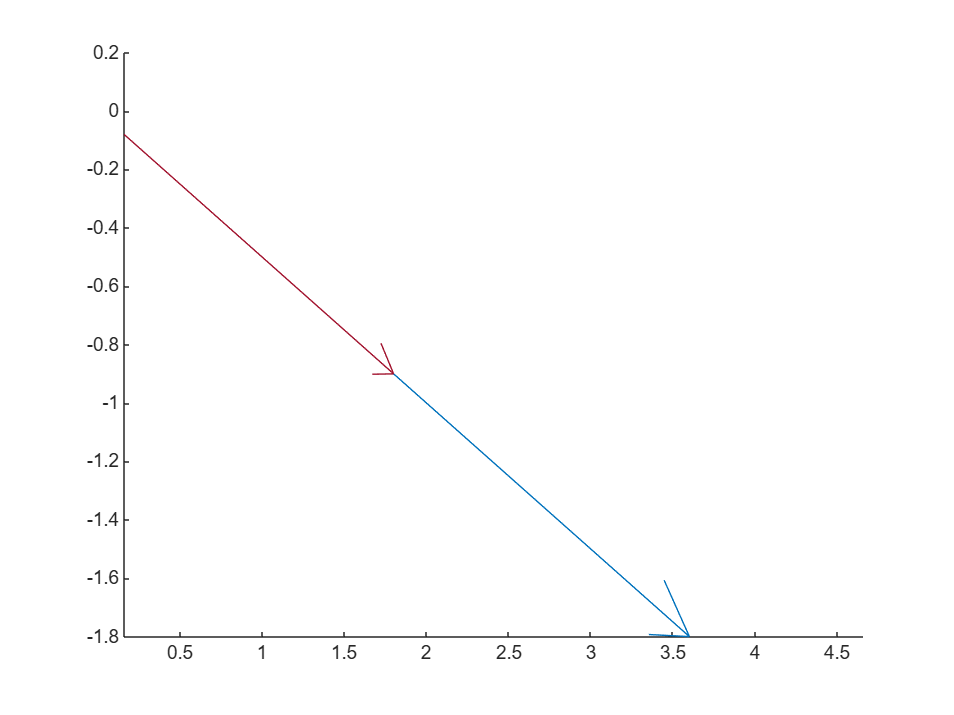

hold on
quiver3(0,0,0,u1(1), u1(2), u1(3))
quiver3(0,0,0,u2(1), u2(2), u2(3))
quiver3(0,0,0,u3(1), u3(2), u3(3))

xlim([0.16 4.66])
ylim([-1.80 0.20])

Inversa de una matriz

A = [ 1 2; -1 0]

A =        1              2       
      -1              0       


iA = inv(A)

iA =        0             -1       
       1/2            1/2     


A*iA

ans =        1              0       
       0              1       


S = [ 1 2 3 ; 4 5 6 ; 3 1 -2]

S =        1              2              3       
       4              5              6       
       3              1             -2       


b= [9 ; 24 ; 4]

b =        9       
      24       
       4       


det(S)

ans =        3       


x = inv(S)*b

x =        4       
      -2       
       3       


x = S\b

x =        4       
      -2       
       3       
